clear all
% data=readtable("C:\Users\thoma\Downloads\book1.xlsx")
% data=readtable("C:\Users\thoma\Documents\optionogaktieprisereurostoxx50pronmdex.xlsx",'Sheet','Sheet1','Range','A2:H1602')
data=readtable("C:\Users\thoma\Documents\Nyeoptioner.xlsx",'Sheet','Sheet2','Range','A1:G1608')

data = 1607×7 table
       Date        Open      High      Low      Close       Volume      SMAVG_15_ 
    __________    ______    ______    ______    ______    __________    __________

    05/04/2019    3445.1    3446.1    3440.3    3441.3             0           NaN
    04/04/2019    3434.3    3449.4    3425.2    3441.9    3.7192e+08    4.7233e+08
    03/04/2019    3399.9    3435.9    3399.9    3435.6    4.1543e+08    4.7874e+08
    02/04/2019    3386.2    3402.8    3382.8    3395.7     3.797e+08    4.7408e+08
    01/04/2019    3353.7      3391    3353.7    3385.4     6.986e+08    4.7086e+08
    29/03/2019    3326.4    3354.3    3326.4    3351.7    4.0559e+08    4.4616e+08
    28/03/2019    3321.3    3337.6    3315.9    3320.3     3.423e+08    4.506


%Vender data om.
data=flipud(data)

data = 1607×7 table
       Date        Open      High      Low      Close       Volume      SMAVG_15_ 
    __________    ______    ______    ______    ______    __________    __________

    31/12/2012    2619.6    2638.2    2619.6    2635.9    1.0315e+08     7.003e+08
    02/01/2013    2659.8    2711.3    2659.8    2711.3    1.0315e+09    7.2357e+08
    03/01/2013    2705.8    2705.8    2689.3    2701.2    8.9775e+08    7.2366e+08
    04/01/2013    2696.9      2711    2690.1    2709.3    8.2507e+08    7.3206e+08
    07/01/2013    2712.3    2714.2      2691    2695.6    8.0569e+08    7.3419e+08
    08/01/2013    2690.9    2710.2    2684.9    2691.4    8.8352e+08     7.524e+08
    09/01/2013    2697.5    2710.5      2691    2706.4    1.0719e+09    7.868

dates=datetime(data.Date,'Convertfrom','excel');
logreturn=[nan;diff(log(data.Close))]*100

logreturn =        NaN
    2.8174
   -0.3706
    0.3005
   -0.5103
   -0.1526
    0.5536
    0.0694
    0.3509
   -0.0968


% Startværdier og begrænsninger for koefficienterne. 
%Første er konstant i varians. Næste er alpha og den sidste er
%risikopræmien
initialvaerdier = [1,0.05,0.9,0.1,0.1]

initialvaerdier =     1.0000    0.0500    0.9000    0.1000    0.1000


Ovenfor=[inf 1 1 inf 1]

Ovenfor =    Inf     1     1   Inf     1


Nedenfor=[0 0 0 0 -1]

Nedenfor =      0     0     0     0    -1


T=size(logreturn,1)

T = 1607

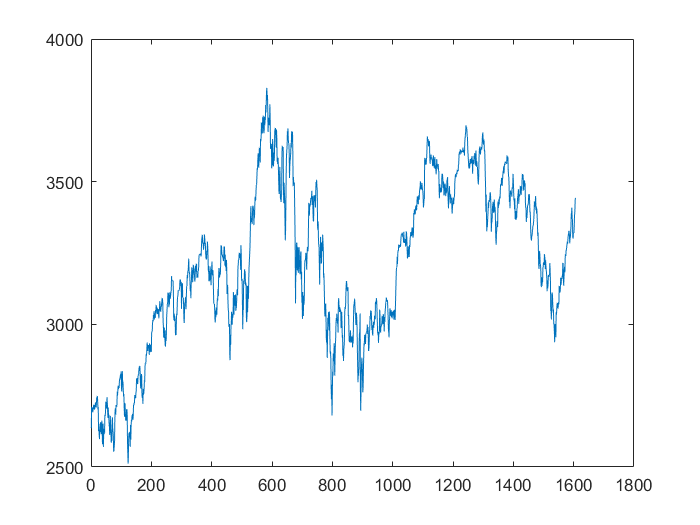

A=[0 1 1 0 0];
b=1;
%backcast funktion til at sætte gang i algoritmen.
w = 0.05*.9.^(0:T-2); 
backCast= w*logreturn(2:end).^2;
%Indstillinger for fmincon.
options = optimset('fmincon');
options.Display = 'iter';
options.Algorithm = 'sqp';
options.Functiontolerance=1/100000000000;
options.TolCon=1/100000000000;
plot(data.Close)

%Det er her jeg kalder funktionen defineret i bunden:
%fejlled=logreturn-r/252+h/2-lambda*sqrt(h). Fejlled=epsilon,
%logreturn=y=det simulerede afkast, h=den betingede varians

% variansen er defineret som h(i)=c+beta*h(i-1)+alpha*(fejlled(i-1)).^2;
% Samme definition som ovenover
 [estimates2,fval,exitflag,output,lambda,gradient,hessian] = fmincon(@ARMA_GARCH,initialvaerdier,A,b,[],[],Nedenfor,Ovenfor,[],options,logreturn(2:end),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    2.455186e+03     0.000e+00     1.000e+00     0.000e+00     2.532e+02  
Objective function returned NaN; trying a new point...
    1          15    2.439270e+03     0.000e+00     3.430e-01     5.973e-01     4.602e+02  
Objective function returned NaN; trying a new point...
    2          26    2.421317e+03     0.000e+00     1.681e-01     2.547e-01     6.305e+02  
    3          45    2.420428e+03     0.000e+00     9.689e-03     1.024e-01     5.698e+02  
    4          55    2.383150e+03     0.000e+00     2.401e-01     3.399e-01     1.195e+02  
    5          62    2.331196e+03     0.000e+00     7.000e-01     7.567e-01     3.914e+02  
    6          75    2.329759e+03     0.000e+00     8.235e-02     6.578e-02     2.059e+02  
    7          84    2.313816e+03     0.000e+00     3.430e-01   


fval

fval = 2.2808e+03

exitflag

exitflag = 2

output

output = struct with fields:
         iterations: 22
          funcCount: 203
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-11.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   2.87e-07                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-11 (selected)'
    constrviolation: 0
           stepsize: 3.6050e-07
       lssteplength: 1
      firstorderopt: 3.9

lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [5×1 double]
         upper: [5×1 double]


%Tjek førsteordensbetingelser.
gradient

gradient = 	1.0e+-3 *

   -0.3357
   -0.3967
   -0.3052
   -0.1221
    0.1526


hessian

hessian = 	1.0e+04 *

    9.2690    7.2618    5.3599    0.0869    0.0041
    7.2618    6.9131    5.5079    0.0377    0.0176
    5.3599    5.5079    4.8243   -0.0227    0.0226
    0.0869    0.0377   -0.0227    0.1707    0.0127
    0.0041    0.0176    0.0226    0.0127    0.1356


eig(hessian)

ans = 	1.0e+05 *

    0.0120
    0.0136
    0.0180
    0.1420
    1.9457


%Tjek for maksimum
any(eig(hessian)<=0)

ans = logical
   0


%Jeg henter fejlled og h ud for at kunne finde standardfejlene.
[ll,lls,h,fejlled]=ARMA_GARCH(estimates2,logreturn(2:end),backCast);
h

h =     0.5647
    0.5295
    0.5069
    0.4835
    0.4844
    0.4625
    0.4619
    0.4384
    0.4262
    0.4080


% News curve og qq plot
 standardfejl=fejlled./sqrt(h)

standardfejl =          0
   -0.4232
    0.3401
   -0.7812
   -0.3108
    0.7403
    0.0679
    0.4670
   -0.1958
   -0.8595


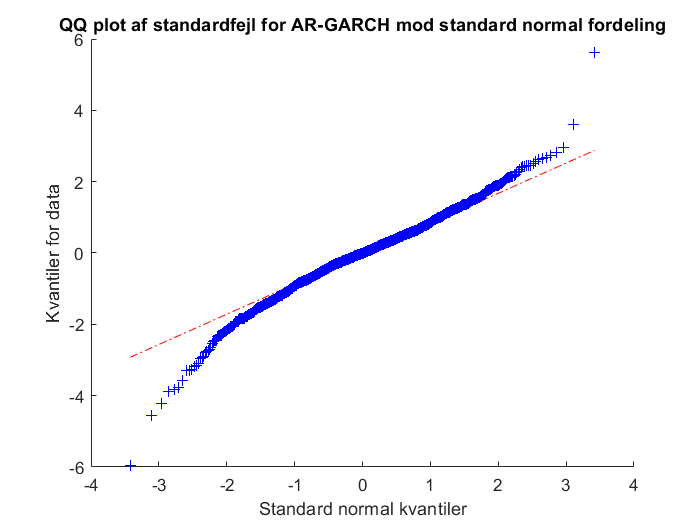

qqplot(standardfejl)
title('QQ plot af standardfejl for AR-GARCH mod standard normal fordeling')
xlabel('Standard normal kvantiler')
ylabel('Kvantiler for data')

gamma=estimates2(:,1)/10000

gamma = 2.8281e-06

beta=estimates2(:,3)

beta = 0.0913

alpha=estimates2(:,2)

alpha = 0.8876

gen= sqrt(nanvar(logreturn))/100

gen = 0.0109

tilfal=rand(1,10000)*4-2

tilfal =    -0.2551   -1.9940   -1.1221   -0.4476    0.8974    1.0684   -1.0372   -1.8581    1.8092    0.1219   -1.3583   -0.5490   -0.8895    0.3228    0.5635   -1.5245   -1.8748   -0.0767   -1.3836    1.7064   -0.3511   -0.3846   -1.3873    1.5003    1.5093   -1.6286   -0.6696    0.7740   -1.3164   -0.6163   -0.5397   -0.6334    1.6616   -1.3151   -1.2265    1.8648   -0.1558    0.9395   -1.6528   -1.1387    0.2823   -0.7057    1.8290    0.3616   -1.5194   -0.8931   -1.4173    0.8766    1.0206    1.3917


tilfal=sort(tilfal)

tilfal =    -1.9997   -1.9983   -1.9980   -1.9980   -1.9979   -1.9978   -1.9976   -1.9975   -1.9975   -1.9974   -1.9972   -1.9971   -1.9959   -1.9958   -1.9950   -1.9946   -1.9941   -1.9940   -1.9940   -1.9931   -1.9930   -1.9924   -1.9924   -1.9908   -1.9906   -1.9906   -1.9904   -1.9892   -1.9891   -1.9891   -1.9883   -1.9881   -1.9873   -1.9872   -1.9869   -1.9864   -1.9846   -1.9843   -1.9842   -1.9840   -1.9828   -1.9825   -1.9816   -1.9815   -1.9812   -1.9809   -1.9797   -1.9795   -1.9790   -1.9789


hi=zeros(1,10000)

hi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


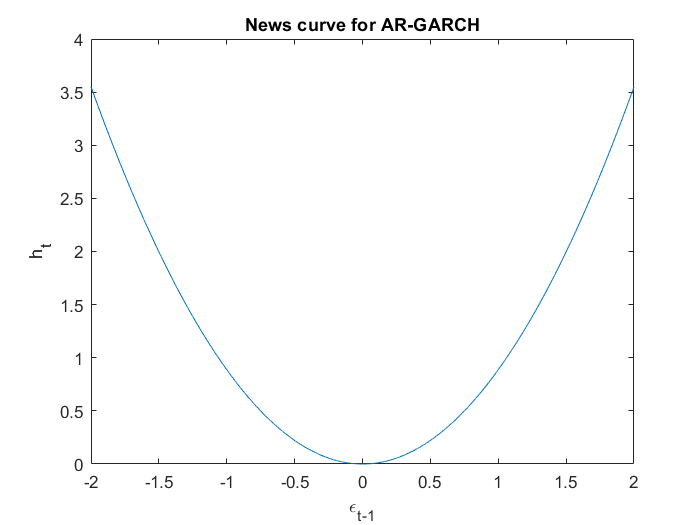

for i=1:10000;
hi(i)=gamma+beta*gen^2+alpha*tilfal(i).^2;
end

plot(tilfal,hi)
title('News curve for AR-GARCH')
xlabel('\epsilon_t_-_1')
ylabel('h_t')



%Standardiseret fejl og test
ll=-ll

ll = -2.2808e+03

bic=aicbic(ll,length(estimates2),length(logreturn(2:end)))

bic = 4.5716e+03

ll=-ll

ll = 2.2808e+03

ll

ll = 2.2808e+03


standardfejl=fejlled./sqrt(h)

standardfejl =          0
   -0.4232
    0.3401
   -0.7812
   -0.3108
    0.7403
    0.0679
    0.4670
   -0.1958
   -0.8595


[h,pValue,stat,cValue]=lbqtest(standardfejl,'lags',5)

h = logical
   0


pValue = 0.1293

stat = 8.5311

cValue = 11.0705

[h,pValue,stat,cValue]=lbqtest(standardfejl.^2,'lags',4)

h = logical
   0


pValue = 0.9224

stat = 0.9147

cValue = 9.4877

%første moment
mean(standardfejl)

ans = -0.0388

%andet moment
mean(standardfejl.^2)

ans = 0.9967

%tredje moment
mean(standardfejl.^3)

ans = -0.4481

%fjerde moment
mean(standardfejl.^4)

ans = 5.3047

%Test statistik. Normalitet
[h,p,jbstat,critval]=jbtest(standardfejl)

h = 1

p = 1.0000e-03

jbstat = 382.2981

critval = 5.9548



% plot(dates(2:end),zminus,'blue',dates(2:end),zplus,'blue',dates(2:end),z,'red')
 

%%%Her regner jeg standardfejlene ud ved sandwhichformlen.
%approximation af differentialet for at beregne varians nedenunder finder jeg I i sandwhichformlen
%Først tager jeg en meget lille ændring til hvert af parametrene.
forskel=0.00001*estimates2

forskel = 	1.0e+-5 *

    0.0283    0.8876    0.0913    0.0443   -0.0380


antal=length(estimates2)

antal = 5

bidrag=zeros(T-1,antal);
for i=1:antal
    j=forskel(i)
    delta=zeros(1,antal);
    delta(i)=j;
%     Jeg finder ændringen i loglikelihood, hvis jeg bruger en smule større og mindre estimater.
    [~, loglikelidtover]= ARMA_GARCH(estimates2+delta,logreturn(2:end),backCast);
    [~, loglikelidtunder]=ARMA_GARCH(estimates2-delta,logreturn(2:end),backCast);
    bidrag(:,i)=(loglikelidtover-loglikelidtunder)/(2*j)
        J_i=bidrag(i)*bidrag(i)'
end

j = 2.8281e-07

bidrag =          0         0         0         0         0
    0.7752         0         0         0         0
    1.6466         0         0         0         0
    1.0783         0         0         0         0
    3.1468         0         0         0         0
    1.9522         0         0         0         0
    4.8981         0         0         0         0
    4.4895         0         0         0         0
    6.1701         0         0         0         0
    1.8736         0         0         0         0


J_i = 0

j = 8.8756e-06

bidrag =          0         0         0         0         0
    0.7752    0.4377         0         0         0
    1.6466    0.8991         0         0         0
    1.0783    0.5730         0         0         0
    3.1468    1.6276         0         0         0
    1.9522    0.9937         0         0         0
    4.8981    2.4430         0         0         0
    4.4895    2.2063         0         0         0
    6.1701    2.9725         0         0         0
    1.8736    0.8848         0         0         0


J_i = 0.6009

j = 9.1342e-07

bidrag =          0         0         0         0         0
    0.7752    0.4377         0         0         0
    1.6466    0.8991    0.0827         0         0
    1.0783    0.5730    0.0576         0         0
    3.1468    1.6276    0.3933         0         0
    1.9522    0.9937    0.2058         0         0
    4.8981    2.4430    0.6758         0         0
    4.4895    2.2063    0.4983         0         0
    6.1701    2.9725    0.6675         0         0
    1.8736    0.8848    0.1733         0         0


J_i = 2.7112

j = 4.4328e-07

bidrag =          0         0         0         0         0
    0.7752    0.4377         0    0.5816         0
    1.6466    0.8991    0.0827   -0.4286         0
    1.0783    0.5730    0.0576    1.1257         0
    3.1468    1.6276    0.3933    0.5438         0
    1.9522    0.9937    0.2058   -1.0240         0
    4.8981    2.4430    0.6758   -0.0727         0
    4.4895    2.2063    0.4983   -0.6928         0
    6.1701    2.9725    0.6675    0.2502         0
    1.8736    0.8848    0.1733    1.3406         0


J_i = 1.1627

j = -3.7974e-07

bidrag =          0         0         0         0         0
    0.7752    0.4377         0    0.5816    1.6387
    1.6466    0.8991    0.0827   -0.4286    0.3153
    1.0783    0.5730    0.0576    1.1257    0.4009
    3.1468    1.6276    0.3933    0.5438   -0.0700
    1.9522    0.9937    0.2058   -1.0240    0.2296
    4.8981    2.4430    0.6758   -0.0727    0.0842
    4.4895    2.2063    0.4983   -0.6928    0.0493
    6.1701    2.9725    0.6675    0.2502    0.2112
    1.8736    0.8848    0.1733    1.3406   -0.1010


J_i = 9.9026


I=bidrag'*bidrag/T

I =   158.2934  109.2448   76.1047   -0.4514   -0.6136
  109.2448   94.9143   73.6580   -1.2447   -1.1522
   76.1047   73.6580   65.6101   -1.1098   -1.7020
   -0.4514   -1.2447   -1.1098    1.2921   -0.0320
   -0.6136   -1.1522   -1.7020   -0.0320    1.0931


%Så skal J findes
J=hessian_beggesider(@ARMA_GARCH, estimates2, logreturn(2:end), backCast)

J = 	1.0e+16 *

   -1.4259   -0.0454   -0.4415   -0.9097   -1.0619
   -0.0454   -0.0014   -0.0141   -0.0290   -0.0338
   -0.4415   -0.0141   -0.1367   -0.2817   -0.3288
   -0.9097   -0.0290   -0.2817   -0.5804   -0.6775
   -1.0619   -0.0338   -0.3288   -0.6775   -0.7908


J=J/T

J = 	1.0e+12 *

   -8.8728   -0.2827   -2.7472   -5.6608   -6.6079
   -0.2827   -0.0090   -0.0875   -0.1804   -0.2106
   -2.7472   -0.0875   -0.8506   -1.7527   -2.0459
   -5.6608   -0.1804   -1.7527   -3.6116   -4.2158
   -6.6079   -0.2106   -2.0459   -4.2158   -4.9212


%Her invetere jeg J.
Jinv=J\eye(length(J))

Jinv =     0.1981   -0.3422    0.1665   -0.1011   -0.2340
   -0.3422    1.0092   -0.7673    0.1785    0.5824
    0.1665   -0.7673    0.7540   -0.0982   -0.4200
   -0.1010    0.1784   -0.0982    1.1793   -0.8415
   -0.2341    0.5825   -0.4201   -0.8414    1.1848



% Så kombineres J og I ved sandwhichformlen
vcv=Jinv*I*Jinv/T

vcv =     0.0006   -0.0010    0.0005   -0.0001   -0.0009
   -0.0010    0.0031   -0.0025   -0.0001    0.0024
    0.0005   -0.0025    0.0026    0.0002   -0.0018
   -0.0001   -0.0001    0.0002    0.0017   -0.0013
   -0.0009    0.0024   -0.0018   -0.0013    0.0030


%Nu tager jeg kvadratroden af diagonalen og får standardafvigelserne for
%parametrene
se=sqrt(diag(vcv))

se =     0.0250
    0.0558
    0.0508
    0.0410
    0.0546


%Så er standardfejlene fundet
estimates2

estimates2 =     0.0283    0.8876    0.0913    0.0443   -0.0380


name={'omega';'alpha';'beta';'phi';'phi1'};





%Her definerer jeg koefficienterne. Jeg dividerer omega som er konstanten i variansen med 100 i anden
omega=estimates2(:,1)/(100.^2) 

omega = 2.8281e-06

omega=estimates2(:,1)

omega = 0.0283

beta=estimates2(:,2)

beta = 0.8876

alpha=estimates2(:,3)

alpha = 0.0913

konstant=estimates2(:,4)

konstant = 0.0443

konstant2=estimates2(:,5)

konstant2 = -0.0380

% lambda=estimates2(:,5)
%Og her smider jeg koefficienterne ind i en tabel for at få overblik
standardafvigelse=[se']

standardafvigelse =     0.0250    0.0558    0.0508    0.0410    0.0546


parametre=[omega alpha beta konstant konstant2]

parametre =     0.0283    0.0913    0.8876    0.0443   -0.0380


tfejl=parametre./standardafvigelse

tfejl =     1.1298    1.6383   17.4622    1.0822   -0.6949


table(name, parametre',standardafvigelse',tfejl')

ans = 5×4 table
     name        Var2         Var3       Var4  
    _______    _________    ________    _______

    'omega'     0.028281    0.025031     1.1298
    'alpha'     0.091342    0.055754     1.6383
    'beta'       0.88756    0.050828     17.462
    'phi'       0.044328    0.040961     1.0822
    'phi1'     -0.037974    0.054647    -0.6949


omega=estimates2(:,1)/(100^2)

omega = 2.8281e-06

[ll,lls,h,fejlled]=ARMA_GARCH(estimates2,logreturn(2:end),backCast);


%Simulation af indeksværdi
%Først trækker jeg noge tilfældige tal fra normalfordelingen
rng(2)
tilfaeldige=randn(502,100000);
%Så allokere jeg plads til variablerne
sigma2=zeros(502,100000);
sigma2(1,:)=h(end)./10000

sigma2 = 	1.0e+-4 *

    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059    0.7059
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

y=zeros(502,100000);
S=zeros(502,100000);
%Jeg definerer den samlede portefølje til en i første periode. obs jeg har
%ændret den fra det simon sagde igen
S(1,:)=data.Close(end)

S = 	1.0e+03 *

    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

S0=data.Close(end)

S0 = 3.4413e+03

%  S(1,:)=data.PX_LAST(end);
 akkumuleretafkast=zeros(502,100000);
 %Jeg simulerer y(t)=r-1/2*h(t)+epsilon(t). Som afkast under Q
 %Den betingede varians er givet ved
 %h(t)=omega+alpha*epsilon(t-1)^2+beta*h(t-1)
 r=(1+0.00122043534)^(1/252)-1;

 tic
for j=1:100000
    for i=2:169
        %sigma2 er den betingede varians
        sigma2(i,j)=omega+beta*sigma2(i-1,j)+alpha*(tilfaeldige(i-1,j)*sqrt(sigma2(i-1,j)))^2;
        %y er det daglige afkast givet ved 
        y(i,j)=sqrt(sigma2(i,j))*tilfaeldige(i,j)+(r)-sigma2(i,j)/2;
        %jeg samler de daglige afkast i r og tager tilsidst eksponential
        %funktionen til r i de enkelte periode.
        akkumuleretafkast(i,j)=y(i,j)+akkumuleretafkast(i-1,j);
        S(i,j)=exp(akkumuleretafkast(i,j))*S0;
    end
end
toc

Elapsed time is 83.271259 seconds.


% %strike
% % K=
y

y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0206    0.0079   -0.0038    0.0023    0.0133    0.0053   -0.0150   -0.0055   -0.0071   -0.0031   -0.0013   -0.0008   -0.0146   -0.0100    0.0041   -0.0068   -0.0044   -0.0047   -0.0003    0.0116    0.0056    0.0044    0.0149   -0.0001    0.0025    0.0026   -0.0167   -0.0048   -0.0100    0.0095    0.0013    0.0066   -0.0035   -0.0084   -0.0087    0.0030   -0.0002   -0.0107   -0.0034   -0.0000    0.0009   -0.0020    0.0169    0.0019    0.0036    0.0029   -0.0128    0.0065    0.0051    0

akkumuleretafkast

akkumuleretafkast =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0206    0.0079   -0.0038    0.0023    0.0133    0.0053   -0.0150   -0.0055   -0.0071   -0.0031   -0.0013   -0.0008   -0.0146   -0.0100    0.0041   -0.0068   -0.0044   -0.0047   -0.0003    0.0116    0.0056    0.0044    0.0149   -0.0001    0.0025    0.0026   -0.0167   -0.0048   -0.0100    0.0095    0.0013    0.0066   -0.0035   -0.0084   -0.0087    0.0030   -0.0002   -0.0107   -0.0034   -0.0000    0.0009   -0.0020    0.0169    0.0019    0.0036    0.0029   -0.0128    0.006

S

S = 	1.0e+03 *

    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413    3.4413
    3.3711    3.4686    3.4284    3.4493    3.4872    3.4596    3.3902    3.4223    3.4171    3.4305    3.4369    3.4386    3.3915    3.4070    3.4556    3.4181    3.4262    3.4252    3.4401    3.4813    3.4605    3.4566    3.4931    3.4408    3.4498    3.4502    3.3843    3.4248    3.4071    3.4740    3.4457    3.4640    3.4294    3.4124    3.4113    3.4515    3.4407    3.4048    3.4296    3.4413    3.4445    3.4343    3.4999    3.4477    3.4538    3.4512    3.3975    3.4636   

faktiskepriser=readtable("C:\Users\thoma\Documents\Nyeoptioner.xlsx",'Sheet','Worksheet')

faktiskepriser = 60×11 table
                               Strike                                    Ticker        Bid     Ask     Last     IVM      Volm    Midtpunkt    Arbejdsdage    Start      Var11   
    _____________________________________________________________    ______________    ____    ____    ____    ______    ____    _________    ___________    _____    __________

    '18-Apr-19 (13d); CSize 10; IDiv 3.65; R -.38; IFwd 3437.18'     ''                 NaN     NaN     NaN       NaN     NaN        NaN          NaN         NaN     05/04/2019
    '3400'                                                       

faktiskepriser=readtable("C:\Users\thoma\Documents\Bachelorprojekt\Nyeoptioner2.xlsx",'Sheet','Ark1','Range','A3:L128')

faktiskepriser = 125×12 table
    Strike           Ticker            Bid      Ask     Last      IVM      Volm     Strike_1    Midtpunkt    Arbejdsdage    x05_04_2019      Var12   
    ______    ____________________    _____    _____    _____    ______    _____    ________    _________    ___________    ___________    __________

     3200     'SX5E 4/18/19 C3200'    243.4      248      246    20.106      288      3200          247           9             NaN        18/04/2019
     3225     'SX5E 4/18/19 C3225'    218.7    223.2      218    18.884      101      3225        220.6        


% 
% % fakoption=faktiskepriser.Last.*(volume>100);
% % sum((fakoption>0))
fakoption=[49.8,36.7,26,15.5,50.3,21.2,58,41.4,92,189.2,90]

fakoption =    49.8000   36.7000   26.0000   15.5000   50.3000   21.2000   58.0000   41.4000   92.0000  189.2000   90.0000


fakoption=faktiskepriser.Midtpunkt

fakoption =   247.0000
  220.6000
  195.1000
  173.0000
  149.7000
  125.5500
  102.5000
   78.0500
   57.1000
   38.0000


Volume=faktiskepriser.Volm

Volume =          288
         101
        3619
        1430
        2306
          93
         708
         190
        3627
        6930


T=faktiskepriser.Arbejdsdage;
likvidefakiotion=fakoption.*(Volume>100).*(T<50)

likvidefakiotion =   247.0000
  220.6000
  195.1000
  173.0000
  149.7000
         0
  102.5000
   78.0500
   57.1000
   38.0000


nanRows=any(isnan(likvidefakiotion),2)

nanRows = 125×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


zeroRows=any(likvidefakiotion==0,2)

zeroRows = 125×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


badRows=nanRows | zeroRows

badRows = 125×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0


likvidefakiotion(badRows, :)=[]

likvidefakiotion =   247.0000
  220.6000
  195.1000
  173.0000
  149.7000
  102.5000
   78.0500
   57.1000
   38.0000
   22.9500


% K=[3425,3450,3475,3500,3400,3425,3450,3475,3500,3400,3450,3475,3500,3400,3500,3400,3425,3450]
% T=[13,13,13,13,42,42,42,42,42,77,77,77,77,105,105,168,168,168]
% nanRows=any(isnan(T),2);
% zeroRows=any(T==0,2);
% badRows=nanRows | zeroRows;
T(badRows, :)=[];
K=faktiskepriser.Strike;

% badRows=nanRows | zeroRows;
K(badRows, :)=[];

T=T'

T =      9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    27    49    49    49    49    49    49    49    49    49    49    49    49    49    49    49    49


K=K'

K =         3200        3225        3250        3275        3300        3350        3375        3400        3425        3450        3475        3500        3525        3550        3575        3600        3200        3250        3325        3350        3375        3400        3425        3450        3475        3500        3525        3550        3575        3600        3625        3650        3200        3300        3325        3350        3375        3400        3425        3450        3475        3500        3525        3550        3600        3625        3650        3675




% % 
% 
r=(1+0.00122043534)^(1/252)-1

r = 4.8401e-06

R=(r+1)

R = 1.0000

antalT=length(T)

antalT = 48

option1maaned=zeros(1,antalT)

option1maaned =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:antalT
option1maaned(i)=mean(max(S(T(i),:)-K(i),0)).*exp(-(R.^T(i)-1));
end
option1maaned

option1maaned =   241.6120  216.7321  191.9655  167.4182  143.2587   97.3212   76.4774   57.8312   41.9418   29.0994   19.3265   12.2956    7.5356    4.4827    2.6063    1.4891  246.6413  200.7585  137.9067  119.1975  101.8631   86.0508   71.8622   59.3257   48.4071   39.0472   31.1801   24.6695   19.3283   15.0358   11.6338    8.9664  258.6613  178.0680  160.1199  143.1883  127.3317  112.6053   99.0437   86.6499   75.4305   65.3242   56.2740   48.2489   35.0007   29.6389   25.0185   21.0520


option1maaned=option1maaned'

option1maaned =   241.6120
  216.7321
  191.9655
  167.4182
  143.2587
   97.3212
   76.4774
   57.8312
   41.9418
   29.0994


xlswrite('C:\Users\thoma\Documents\Bachelorprojekt\optionertillatex',option1maaned,'xlRange','H1:H63')
option1maaned=option1maaned'

option1maaned =   241.6120  216.7321  191.9655  167.4182  143.2587   97.3212   76.4774   57.8312   41.9418   29.0994   19.3265   12.2956    7.5356    4.4827    2.6063    1.4891  246.6413  200.7585  137.9067  119.1975  101.8631   86.0508   71.8622   59.3257   48.4071   39.0472   31.1801   24.6695   19.3283   15.0358



for i=1:antalT
SE(i)=(option1maaned(i)-likvidefakiotion(i)).^2;
end

S0./K

ans =     1.0754    1.0671    1.0589    1.0508    1.0428    1.0272    1.0196    1.0121    1.0048    0.9975    0.9903    0.9832    0.9762    0.9694    0.9626    0.9559    1.0754    1.0589    1.0350    1.0272    1.0196    1.0121    1.0048    0.9975    0.9903    0.9832    0.9762    0.9694    0.9626    0.9559


%Fordelt på moneyness
%Total
RMSEtot=sqrt(mean(SE))

RMSEtot = 28.1141


%under 0.95
j=S0./K<=0.95

j = 1×48 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 17.2386

%0.975 til 0.95
j= 0.975>=S0./K & S0./K>0.95

j = 1×48 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 18.1142

%1 til 0.975
j=1>=S0./K & S0./K>=0.975

j = 1×48 logical array
   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 28.0288

%1.025 til 1
j=1.025>=S0./K & S0./K>1

j = 1×48 logical array
   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 32.6467

%1.05 til 1.025
j=1.05>=S0./K & S0./K>1.025

j = 1×48 logical array
   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 37.1121

%Over 1.05
j=S0./K>1.05

j = 1×48 logical array
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 27.1708


%Hvor der kun er tre slags moneyness
%Out of money
j=S0./K<=0.95

j = 1×48 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 17.2386

%At the money
j= 1.05>=S0./K & S0./K>0.95

j = 1×48 logical array
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 29.4796

%In the money
j=S0./K>1.05

j = 1×48 logical array
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 27.1708


%total
RMSEtot=sqrt(mean(SE))

RMSEtot = 28.1141

j=T==9

j = 1×48 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 4.7175

j=T==27

j = 1×48 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


%første måned
RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 26.1608

%anden måned
j=T==49

j = 1×48 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


RMSEtot=sqrt(sum(SE.*j)./sum(j))

RMSEtot = 40.7991

%tredje måned
% j=T==69
% RMSEtot=sqrt(sum(SE.*j)./sum(j))
% %fjerde måned
% j=T==89
% RMSEtot=sqrt(sum(SE.*j)./sum(j))
% 
% %Sjette måned
% j=T==114
% RMSEtot=sqrt(sum(SE.*j)./sum(j))

%Implieds
r=(1+0.00122043534)^(1/252)-1;
x=-850:10:850

x =   -850  -840  -830  -820  -810  -800  -790  -780  -770  -760  -750  -740  -730  -720  -710  -700  -690  -680  -670  -660  -650  -640  -630  -620  -610  -600  -590  -580  -570  -560


K=S0+x

K =     2.5913    2.6013    2.6113    2.6213    2.6313    2.6413    2.6513    2.6613    2.6713    2.6813    2.6913    2.7013    2.7113    2.7213    2.7313    2.7413    2.7513    2.7613    2.7713    2.7813    2.7913    2.8013    2.8113    2.8213    2.8313    2.8413    2.8513    2.8613    2.8713    2.8813


tic
for j=1:49
for i=1:171
option(i,j)=mean(max(S(j+8,:)-K(i),0))*exp(-((1+r).^(j)-1));
end
end
toc

Elapsed time is 14.935825 seconds.


antaldage=1:49

antaldage =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


x=-850:10:850

x =   -850  -840  -830  -820  -810  -800  -790  -780  -770  -760  -750  -740  -730  -720  -710  -700  -690  -680  -670  -660  -650  -640  -630  -620  -610  -600  -590  -580  -570  -560


K=S0+x

K =     2.5913    2.6013    2.6113    2.6213    2.6313    2.6413    2.6513    2.6613    2.6713    2.6813    2.6913    2.7013    2.7113    2.7213    2.7313    2.7413    2.7513    2.7613    2.7713    2.7813    2.7913    2.8013    2.8113    2.8213    2.8313    2.8413    2.8513    2.8613    2.8713    2.8813


[Antaldage,K1]=meshgrid(antaldage,K)

Antaldage =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    1

K1 =     2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913    2.5913
    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013    2.6013
    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113    2.6113
    2.6213    2.6213    2.6213    2.6213    2.6213    2.6213    2.6213    2.6213    2.6213  

Antaldage=Antaldage

Antaldage =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
     1     2     3     4     5     6     7     8     9    10    11    12    13    1

option

option =   850.2109  850.2855  850.2985  850.2312  850.0789  850.2354  850.2398  850.1804  850.3301  850.3430  850.3213  850.2934  850.3423  850.4944  850.5284  850.6311  850.5671  850.5613  850.7927  850.7609  850.9522  850.9298  850.7822  850.9567  851.0386  851.1582  851.1550  851.2948  851.4165  851.3564
  840.2109  840.2855  840.2986  840.2314  840.0791  840.2357  840.2402  840.1808  840.3305  840.3435  840.3218  840.2940  840.3430  840.4951  840.5291  840.6319  840.5679  840.5621  840.7937  840.7619  840.9534  840.9311  840.7834  840.9581  841.0402  841.1599  841.1571  841.2970  841.4191  841.3590
  830.2110  830.2856  830.2988  830.2316  830.0794  830.2360  830.2405  830.1812  830.3309  830.3440  830.3223  830.2946  830.3437  830.4958  830.5298  830.6327  830.5688  830.5630  830.7946  830.7630  830.9546  830.9325  830.7847  830.9596  831.0418  831.1616  831.1596  831.2996  831.4218  831.3617
  820.2110  820.2857  820.2989  820.2318  820.0796  820.2363  820.2408  820.1816  820.33

r=.00122043534

r = 0.0012

Volatility = blsimpv(S0,K1,r,Antaldage./252,option);
implieds=Volatility

implieds =     1.5859    1.1511    0.9400    0.7862    0.5806    0.6348    0.5849    0.5176    0.5332    0.5060    0.4747    0.4443    0.4358    0.4440    0.4318    0.4285    0.4073    0.3936    0.4041    0.3903    0.3939    0.3826    0.3627    0.3664    0.3632    0.3619    0.3544    0.3541    0.3526    0.3437
    1.5661    1.1368    0.9283    0.7764    0.5732    0.6268    0.5776    0.5111    0.5266    0.4997    0.4688    0.4387    0.4303    0.4385    0.4264    0.4232    0.4022    0.3887    0.3991    0.3855    0.3891    0.3779    0.3582    0.3619    0.3588    0.3575    0.3501    0.3498    0.3484    0.3395
    1.5463    1.1225    0.9167    0.7666    0.5658    0.6189    0.5703    0.5046    0.5200    0.4934    0.4629    0.4332    0.4249    0.4330    0.4211    0.4179    0.3972    0.3839    0.3942    0.3807    0.3843    0.3733    0.3538    0.3575    0.3544    0.3532    0.3458    0.3456    0.3442    0.3354
    1.5266    1.1083    0.9051    0.7568    0.5584    0.6110    0.5630    0.4981    0.

toc

Elapsed time is 17.567474 seconds.


K=S0./K

K =     1.3280    1.3229    1.3179    1.3128    1.3078    1.3029    1.2980    1.2931    1.2883    1.2834    1.2787    1.2739    1.2692    1.2646    1.2600    1.2554    1.2508    1.2463    1.2418    1.2373    1.2329    1.2285    1.2241    1.2198    1.2155    1.2112    1.2069    1.2027    1.1985    1.1944


% %Figur af smil
K1=K1/S0

K1 =     0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530    0.7530
    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559    0.7559
    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588    0.7588
    0.7617    0.7617    0.7617    0.7617    0.7617    0.7617    0.7617    0.7617    0.7617  

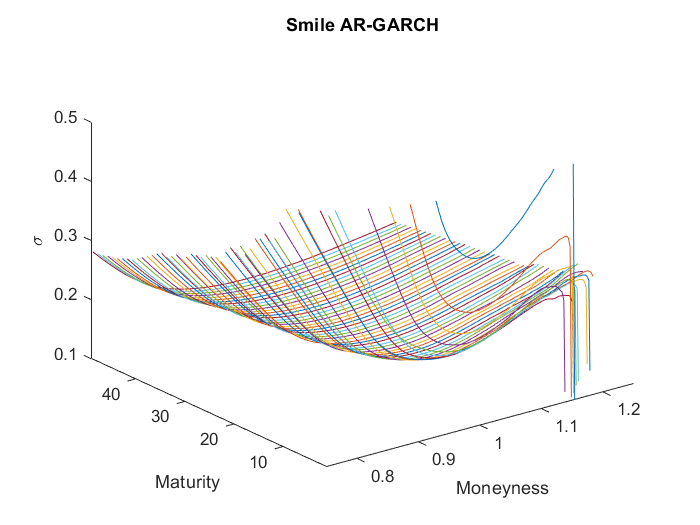

plot3(K1,Antaldage,implieds)
title('Smile AR-GARCH')
xlabel('Moneyness')
ylabel('Maturity')
zlabel('\sigma')
ylim([1 49])
xlim([0.75 1.25])
zlim([0.1 0.5])

function [ll,lls,h,fejlled]=ARMA_GARCH(parameters, logreturn, backCast)

c=parameters(1);
beta=parameters(2);
alpha=parameters(3);
konstant=parameters(4);
konstant2=parameters(5);

T=size(logreturn,1);
h=zeros(T,1);
h(1)=backCast;
fejlled=zeros(T,1);
%Jeg issolerer for fejlled i ligningen for afkast under P

for i=2:T
    fejlled(i)=logreturn(i)-konstant-konstant2*logreturn(i-1);
    h(i)=c+beta*h(i-1)+alpha*(fejlled(i-1)).^2;
    
end
% v=length(logreturn)-length(parameters);
% if v<50
%     v = 2 + exp(v);
% else
%     v = 50 + log(v);
% end
 lls= 0.5*(log(pi*2)+log(h)+fejlled.^2./h);
% lls=1/2*(log(h)+(v+1)*log(1+fejlled.^2./(h.*(v-1))));

ll=  sum(lls);
end

% Det her er funktion der finder J i sandwhichformlen der bliver brugt til at finde variansen:
%J er her givet ved: J(i,j)=(f(parametre+en lille ændring i to
%dimensioner)-f(parametre+lille ændring i en af
%parameter)-f(parametrene+lille ændring i den anden
%parametre)+f(parametrene))/(den lille ændring i hvet af parametrene ganget
%sammen).
function H= hessian_beggesider(funktion,parametre,varargin)
if size(parametre,2)>size(parametre,1)
    parametre=parametre';
end
%Jeg evaluere funktion med parametrene 
f=feval(funktion,parametre,varargin{:});
%En meget lille ændring af parametrene.
h=abs(parametre)*0.00001;
parametreh=h+parametre;
h=parametreh-parametre;
h=diag(h);

antal=size(parametre);

afledtep=zeros(antal);
afledten=zeros(antal);
%Jeg finder scoren lidt til over og under parametre væriderne.
for i=1:antal
    afledtep(i)=feval(funktion, parametre+h(:,i),varargin{:});
    afledten(i)=feval(funktion, parametre-h(:,i),varargin{:});
end
andenafledtep=zeros(antal);
andenafledten=zeros(antal);
%Nedenunder finder jeg de andenafledte ved at ændre to variable samtidigt.
for j=1:antal
    for i=j:antal
        andenafedtep(i,j)=funktion(parametre+h(:,j)+h(:,i),varargin{:});
        andenafledtep(j,i)=andenafledtep(i,j);
        andenafledten(i,j)=funktion(parametre-h(:,j)-h(:,i),varargin{:});
        andenafledten(j,i)=andenafledten(i,j);
    end
end
H=zeros(antal);
diagonal=diag(h);
GH=diagonal*diagonal';
%Tilsidst samles det hele sådan at J fås  
for i=1:antal
    for j=i:antal
        H(i,j)=(andenafledtep(i,j)+andenafledten(i,j)-afledtep(i)-afledten(i)-afledtep(j)-afledten(j)+f+f)/GH(i,j)/2;
        H(j,i)=H(i,j);
    end
end
end
